# Fumbol

**Yaiza Cano, Narcís Terrado**

## 1. Escollir imatge i patró.

Primerament escollirem la imatge que voldrem utilitzar com a model i escollirem un tros d'imatge que serà el nostre patró.

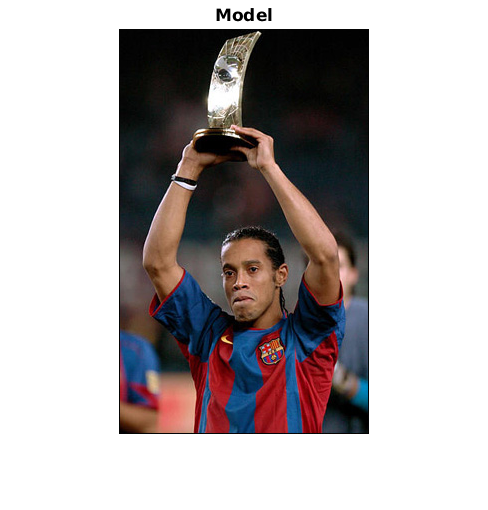

model = imread('model.jpg');
figure, imshow(model); title('Model');

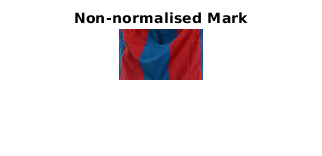


pattern = model(350:400,87:170,:);
figure, imshow(pattern); title('Non-normalised Mark');

## 2. Normalitzar colors i extreure'n l'histograma

Un cop escollit el patró, hem d'extreure els colors per fer l'histograma però, abans d'això, hem de normalitzar els colors per tal que la il·luminació de la imatge no afecti a les dades que volem extreure.

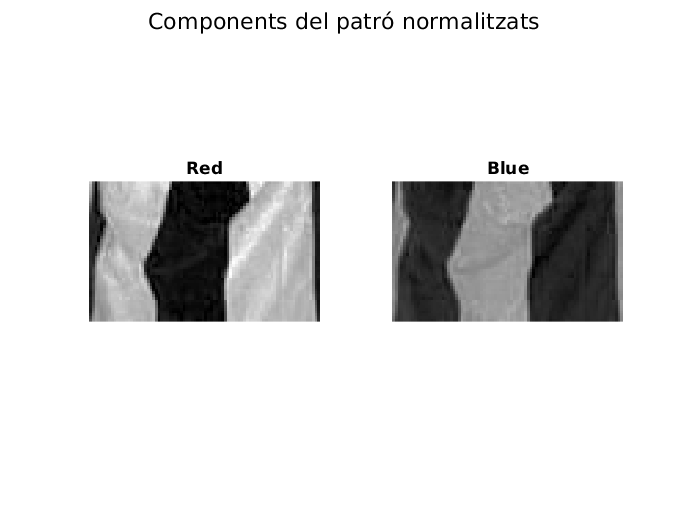

np = NormalizeRB(model); % Normalitzem tota la imatge
np = np(350:400,87:170,:); % Agafem el patró ara normalitzat
%norm = normalizeRB(model);
%imshow(norm)


figure, sgtitle('Components del patró normalitzats')
subplot(1,2,1);imshow(np(:,:,1)); title('Red')
subplot(1,2,2);imshow(np(:,:,2)); title('Blue')

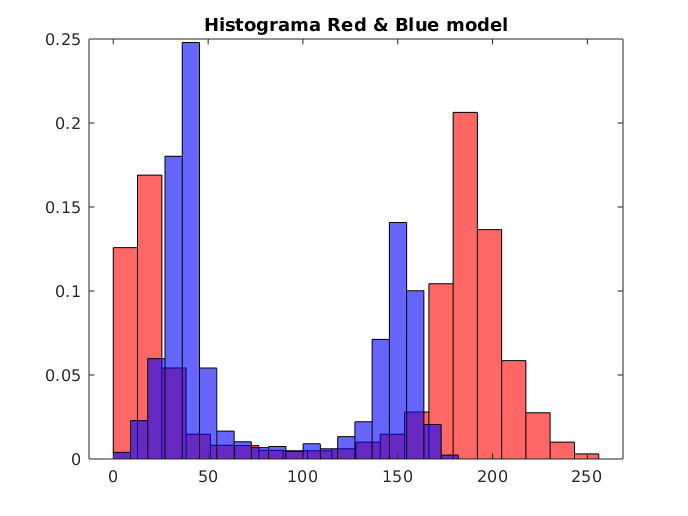



figure, [red, blue] = histRB(np, 20); title('Histograma Red & Blue model');

%figure, imhist(np), title('Histograma gris'); %Dubtosa utilitat

## 3. Imatges a comprarar (title wip)

Un cop tenim el histograma model, escollim una imatge del mateix equip (Barça) i una d'un altre equip, per extreure un patro i comparar-ne els histogrames. (Basicament testing o whatever)

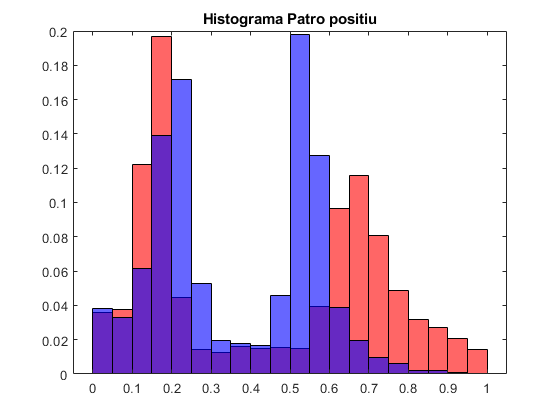

positive = imread('positiu.jpg');
%[J, rect] = imcrop(positive)
positive = NormalizeRB(positive);
pos_pat = positive(85:170,150:210,:);


negative = imread('negatiu.jpg');
negative = NormalizeRB(negative);
neg_pat = negative(110:210, 80:180,:);

figure, [pos_red, pos_blue] = histRB(pos_pat, 20); title('Histograma Patro positiu');

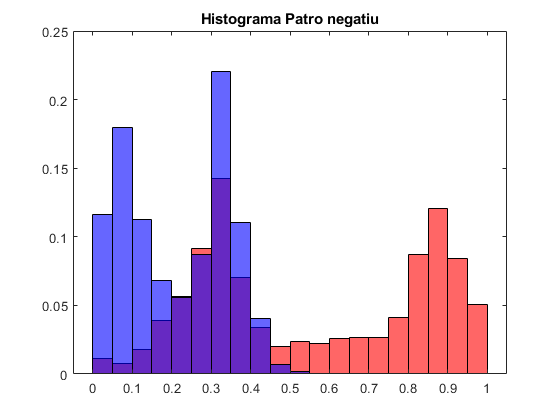

figure, [neg_red, neg_blue] = histRB(neg_pat, 20); title('Histograma Patro negatiu');


pos_hist = imhist(pos_pat);
neg_hist = imhist(neg_pat);
%imshow(pos_norm), title('Positiu normalitzat');
%imshow(neg_norm), title('Negatiu normalitzat');

%s'ha de fer el histograma pero no se si amb RGB o nomes amb RB
%

## 4. Comparació d'histogrames

### Root mean squared error: 

Es compara l'arrel quadrada de la mitjana de la diferencia al quadrat de cada valor dels histogrames.

rmse_red_pos = sqrt(mean((red.Values - pos_red.Values).^2));

Dot indexing is not supported for variables of this type.

rmse_blue_pos = sqrt(mean((blue.Values - pos_blue.Values).^2));
rmse_pos = (rmse_red_pos + rmse_blue_pos) /2;

rmse_red_neg = sqrt(mean((red.Values - neg_red.Values).^2));
rmse_blue_neg = sqrt(mean((blue.Values - neg_blue.Values).^2));
rmse_neg = (rmse_red_neg + rmse_blue_neg) /2;


### Kullback–Leibler divergence

Es prenen els histogrames com una distribució probabilistica. He copiat una funcio ja feta.

Com mes proper a 0, més semblant

[https://en.wikipedia.org/wiki/Kullback%E2%80%93Leibler_divergence](https://en.wikipedia.org/wiki/Kullback%E2%80%93Leibler_divergence)

dif_pos = KLDiv(red.Values, pos_red.Values);
dif_pos = (KLDiv(blue.Values, pos_blue.Values) + dif_pos ) /2;

dif_pos = 0.9538


KLDiv(blue.Values, neg_blue.Values);

ans = Inf


dif_neg = KLDiv(red.Values, neg_red.Values);

dif_neg = 1.3962

dif_neg = (KLDiv(blue.Values, neg_blue.Values) + dif_neg ) /2;

dif_neg = Inf

Per alguna rao es infinit.... idk...

És per l'ordre, ho estaves fent al revés.